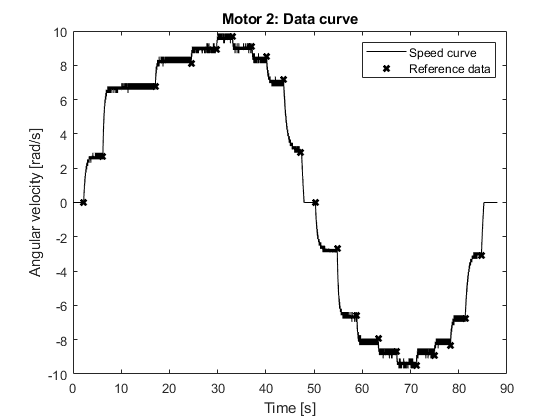

clear all
load Motor2

xlabel('Tiempo [s]')
ylabel('Velocidad [Rad/s]')
M2x=[];M2y=[];


M2x=[];M2y=[];
%primer"semiciclo"

%dinamica subida
M2x(1)=2.23;M2y0(1)=0;
M2x(2)=6.2;M2y0(2)=2.707;
M2x(3)=17.1;M2y0(3)=6.769;
M2x(4)=24.51;M2y0(4)=8.122;
M2x(5)=29.81;M2y0(5)=8.896;
%dinamica de bajada
M2x(6)=33.06;M2y0(6)=9.669;
M2x(7)=37.1;M2y0(7)=9.089;
M2x(8)=40.14;M2y0(8)=8.509;
M2x(9)=43.68;M2y0(9)=7.155;
M2x(10)=47.1;M2y0(10)=ControlOutput(M2x(10)/.005);

%segundo "semiciclo"

%dinamica bajada
M2x(11)=50.28;M2y0(11)=0;
M2x(12)=54.79;M2y0(12)=-2.707;
M2x(13)=58.87;M2y0(13)=-6.575;
M2x(14)=63.28;M2y0(14)=-7.929;
M2x(15)=67.17;M2y0(15)=-8.702;
%dinamica de subida
M2x(16)=71.2;M2y0(16)=-9.476;
M2x(17)=74.92;M2y0(17)=-8.896;
M2x(18)=78.28;M2y0(18)=-8.316;
M2x(19)=81.36;M2y0(19)=-6.769;
M2x(20)=84.69;M2y0(20)=-3.094;

plot (X_Value,ControlOutput,'k')
hold on
plot(M2x,M2y0,'xk','LineWidth',2)
xlabel('Time [s]')
ylabel('Angular velocity [rad/s]')
title('Motor 2: Data curve')
legend('Speed curve','Reference data')
hold off



M2tamano=length(M2x)-1;
M2escalon=cell(M2tamano,2);
for i=1:M2tamano
    aux=(ControlOutput(M2x(i)/0.005));
    M2escalon{i,2}= ControlOutput(M2x(i)/0.005:M2x(i+1)/0.005)-aux;
    M2escalon{i,1}= linspace(0,M2x(i+1)-M2x(i),length(M2escalon{i,2}));
end
M2k=[];
M2Tao=[];
M2idx=[];
M2Funcion=cell(M2tamano,1);
M2Filtro=cell(M2tamano,1);

for i=1:M2tamano
    M2k(i)=mean(M2escalon{i,2}(end-100:end))-M2escalon{i,2}(1);
    [na,aux1]=min(abs(M2escalon{i,2}-0.63*M2k(i)));
    [na,aux2]=min(abs(M2escalon{i,2}-0.28*M2k(i)));
    M2Tao(i)=1.5*(M2escalon{i,1}(aux1)-M2escalon{i,1}(aux2));
    M2Funcion{i,1} = tf(M2k(i),[M2Tao(i),1]);
    
%     filtro
    M2Filtro{i,1} = tf(1,[M2Tao(i)/10,1]);
end

M2k, M2Tao

M2k =     2.7132    4.1052    1.5356    0.4691    0.7008   -0.6548   -0.5266   -1.3288   -3.9156   -2.9008   -2.8242   -3.9654   -1.5452   -0.4672   -0.4921    0.7046    0.5610    1.3729    3.5729


M2Tao =     0.3675    0.2325    0.1650    0.1200   -0.0075    0.0675    0.1650    0.1875    0.6000    0.2250    0.3900    0.2550    0.1350    0.1275    0.0150    0.0600    0.0900    0.1200    0.5325


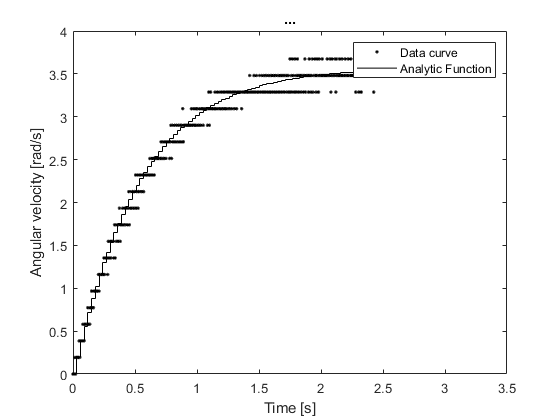

M2graficar=19;
plot(M2escalon{M2graficar,1},M2escalon{M2graficar,2},'.k')
hold on
[M2yAux,M2xAux]=step(M2Funcion{M2graficar},3);
stairs(M2xAux,M2yAux,'k')
xlabel('Time [s]')
ylabel('Angular velocity [rad/s]')
title('...')
legend('Data curve','Analytic Function')
hold off


M2T=0.005;
% 

M2Filtrodigital=cell(M2tamano,1);
M2numfiltrodigital=zeros(M2tamano,1);
M2denfiltrodigital=zeros(M2tamano,1);

for i=1:M2tamano
    M2Filtrodigital{i,1} = c2d(M2Filtro{i,1},M2T);
    
    M2numfiltrodigital(i)=M2Filtrodigital{i}.num{1}(end);
    M2denfiltrodigital(i)=M2Filtrodigital{i}.den{1}(end);
end


aplicando el filtro

ecuacion en diferencias

y_k=num*x_k-1+den*y_k-1


M2Y=cell(M2tamano,1);

for j=1:M2tamano
M2y=[0];

aux1 = M2escalon{j,1};
aux2 = M2escalon{j,2};

for i=2:length(aux2) %para y valor actual comienza en 2
    M2y(i)=M2numfiltrodigital(j)*aux2(i-1)-M2denfiltrodigital(j)*M2y(i-1);
end

M2Y{j}=M2y;
end

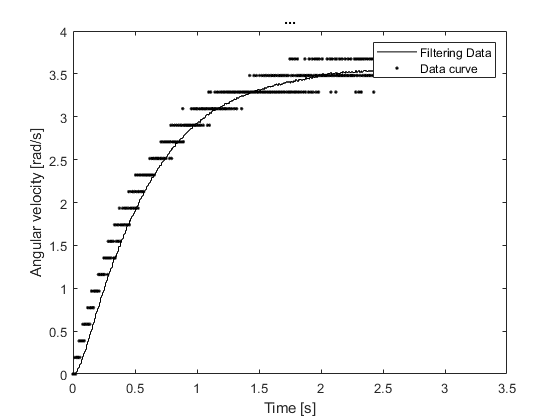


stairs(M2escalon{M2graficar,1},M2Y{M2graficar},'k')
hold on
plot(M2escalon{M2graficar,1},M2escalon{M2graficar,2},'.k')  % al aplicar el filtro se agrega un retardo
xlabel('Time [s]')
ylabel('Angular velocity [rad/s]')
title('...')
legend('Filtering Data','Data curve')
hold off

Errores

M2Error2medio=(M2Y{M2graficar}'-M2escalon{M2graficar,2})'*(M2Y{M2graficar}'-M2escalon{M2graficar,2})/length(M2escalon{M2graficar,1})

M2Error2medio = 0.0203

 for i=1:M2tamano
    M2Error2medios(i)=(M2Y{i}'-M2escalon{i,2})'*(M2Y{i}'-M2escalon{i,2})/length(M2escalon{i,1});
 end
 M2Error2medios

M2Error2medios =     0.0120    0.0144    0.0155    0.0171       Inf    0.0192    0.0161    0.0158    0.0230    0.0061    0.0133    0.0198    0.0184    0.0181    0.0339    0.0242    0.0220    0.0199    0.0203
